# Linear Control Design II - Group Work Problem Module 20

## Description

Module 20 focuses on experiments with white noise. It is often necessary to calculate the average and root mean square (rms) values of a stochastic signal during simulations. Problem 6.5 in the textbook addresses the solution of this issue, which is based on the construction of two differential equations that can do this on line. These solutions are given below:


$$\frac{dv_{avg}}{dt}=\frac{1}{t}(-v_{avg}+u) \qquad (1)$$


where *v_avg* is the average value and *u* is the input. The rms value of a signal can be found from equation:


$$\frac{dv_{rms}}{dt}=\frac{1}{2t}(-v_{rms}+\frac{1}{v_{rms}}u^2) \qquad (2)$$


**Problem 1**

Given the formulas in Problem 6.5, show how Equations (1) and (2) can be obtained.

a. What is the mathematical relation between the rms value of a signal and the statistical parameters of the signal (mean and variance)?

b. Equations 1 and 2 are two scalar linear time-varying systems. Are they asymptotically stable? Do they represent a practical solution to the averaging problem?

c. What is their main failing?

**Solution:**

**a)     **$X_{rms}=\sqrt{E\{X^2\}}\\
\sigma^2=E\{X^2\}-(E\{X\})^2$    

        Mean value

        
$$E\{X\}^2=m^2$$


        
$$X_{rms}=\sqrt{\sigma^2+m^2}$$


**b)    **

**Problem 2**

Use the Equations 1 and 2 to calculate the mean and variance of the signals from the Uniform, *U*(0.5,1/2), and Gaussian distributed (Random Number) noise generators of the Matlab/Simulink package. The notation *U*(0.5,1/2) means uniformly distributed with a mean value 0.5 and variance 1/2 ($\sigma$); whereas *N*(0,1) means normally distributed with a mean value of 0 and a variance of 1 ($\sigma$). Use a generator sample time of 1 s, simulate over 100 s and plot the results. Then use a sample time of 0.1 s and simulate over 10 s. The variable *t* can be obtained by using the clock in the Simulink *Source* menu. Simulate over a time interval which is sufficient to obtain a reasonably smooth response and try different noise generator seeds and sample times. Use the standard integration routine rk45 (Runga Kutta).

a. Do simulation results agree with what is expected? Are the obtained mean and standard deviations correct? Explain.


$$\frac{dv_{avg}}{dt}=\frac{1}{t}(-v_{avg}+u) \qquad (1)
$$



$$\frac{dv_{rms}}{dt}=\frac{1}{2t}(-v_{rms}+\frac{1}{v_{rms}}u^2) \qquad (2)$$


clear
% Fill in your answer here:
tc = 100; % simulation time
vstd = 1; % variance 
vmean = 0; % mean value

% for uniform distribution 
% variance: sigma^2 = 1/12 * (b-a)^2
% mean:  mu = 1/2*(a+b)
% a = mu - sigma*sqrt(3)
% b = mu + sigma*sqrt(3)

nmax = vmean + vstd*sqrt(3);
nmin = vmean - vstd*sqrt(3);

for i = 1:1
    seed = i*11;
    [t1,x1,y1] = sim('m20p2', [0.01 1000]);
    xs(i,:,:) = x1(:,:);
    ys(i,:,:) = y1(:,:);
end

xm = mean(xs,1);
ym = mean(ys,1);

%% from setup
%  root mean square expection
vrmsexp = sqrt(vmean^2+vstd^2)

vrmsexp =      1


% variance of generator
varmeas = var(ys(1,:,3)) 

varmeas =       0.98168


%% from generator
% mean of generator
mmeas = mean(ys(1,:,3))

mmeas =    0.00073367


% root mean square of generator
vrmsmeas = sqrt(mmeas^2+varmeas)

vrmsmeas =        0.9908


%% from equation
% mean value from mean equation
mm = mean(ys(1,end/2:end,1))

mm =      0.024488


% rms from rms equation
mrms = mean(ys(1,end/2:end,2))

mrms =        1.0007


% variance of equation
varmm = mrms^2-mm^2

varmm =        1.0008


**Problem 3**

Instead of t in the equations above, use a time constant $\tau$=100 s. Simulate the differential equations using this simpliffication.

a. Do the results of this simulation agree with those found in Problem 2? Explain.

b. What is the practical application of your results?

% Fill in your answer here:
[tsc, xsc, ysc] = sim('m20p3.slx',[0.01 1000]);

% variance of generator
varmeasc = var(ysc(:,3)) 

varmeasc =       0.99016


%% from generator
% mean of generator
mmeasc = mean(ysc(:,3))

mmeasc =    -0.0016799


% root mean square of generator
vrmsmeas = sqrt(mmeas^2+varmeas)

vrmsmeas =        0.9908


%% from equation
% mean value from mean equation
mmc = mean(ysc(end/2:end,1))

mmc =     -0.035141


% rms from rms equation
mrmsc = mean(ysc(end/2:end,2))

mrmsc =       0.99504


% variance of equation
varmm = mrms^2-mm^2

varmm =        1.0008


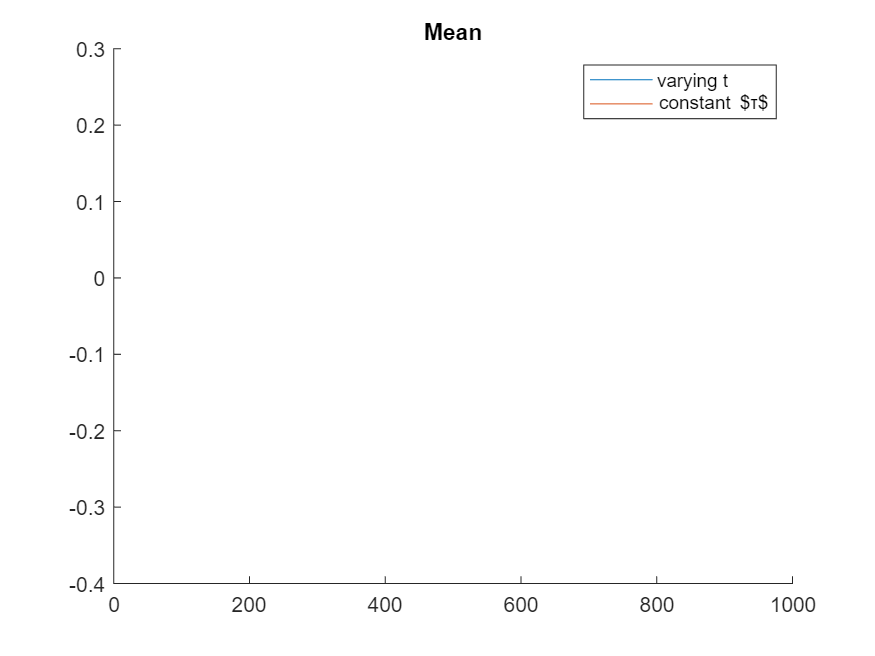

figure
hold all
plot(t1,ym(1,:,1));
plot(tsc,ysc(:,1))
legend('varying t','constant $\tau$');
title('Mean');

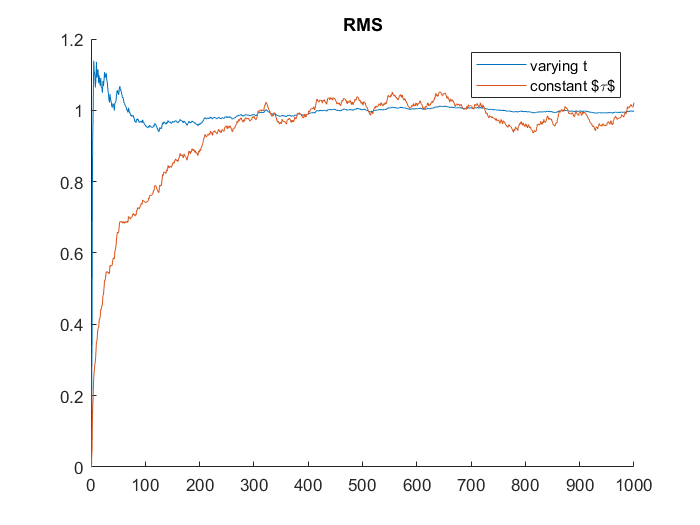

figure
hold all
plot(t1,ym(1,:,2));
plot(tsc,ysc(:,2))
legend('varying t','constant $\tau$');
title('RMS');

**Problem 4**

Add two different noise signals together (different seeds and variances) and use Equations 1 and 2 to find their means and standard deviations.

a. What do the results show about the rule for adding noise signals?

% Fill in your answer here:
seed2 = 345;
vstd2 = 0.5;
vmean2 = 0.5;
nmax2 = vmean2 +vstd2*sqrt(3);
nmin2 = vmean2 -vstd2*sqrt(3);

[tss, xss, yss] = sim('m20p4.slx', [0.01 5000]);

%% from generator
% mean of generator
mmeass = mean(yss(:,3))

mmeass =        0.5117


% root mean square of generator
vrmsmeas = sqrt(mmeas^2+varmeas)

vrmsmeas =        0.9908


%% from equation
% mean value from mean equation
mms = mean(yss(end/2:end,1))

mms =       0.50645


% rms from rms equation
mrmss = mean(yss(end/2:end,2))

mrmss =        1.2277


% variance of equation
varmm = mrms^2-mm^2

varmm =        1.0008


% expection
exprmss = sqrt(vstd2^2+vstd^2+(vmean2+vmean)^2)

exprmss =        1.2247


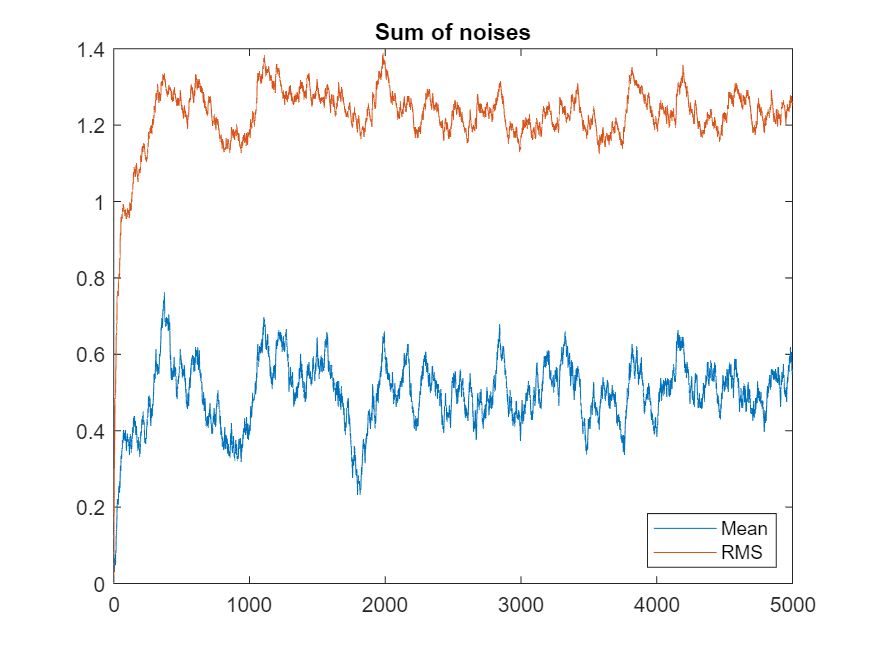

figure
plot(tss,yss(:,1:2))
title('Sum of noises');
legend('Mean','RMS','location','southeast');

**Problem 5**

Assume that the available noise generators can deliver an approximation to white noise.

a. Construct a Wiener Process and use two such processes to construct a random walk process in two dimensions. Demonstrate graphically that this two dimensional process works as expected. Compare your results to those in Figures 6.11-6.13 in the textbook.

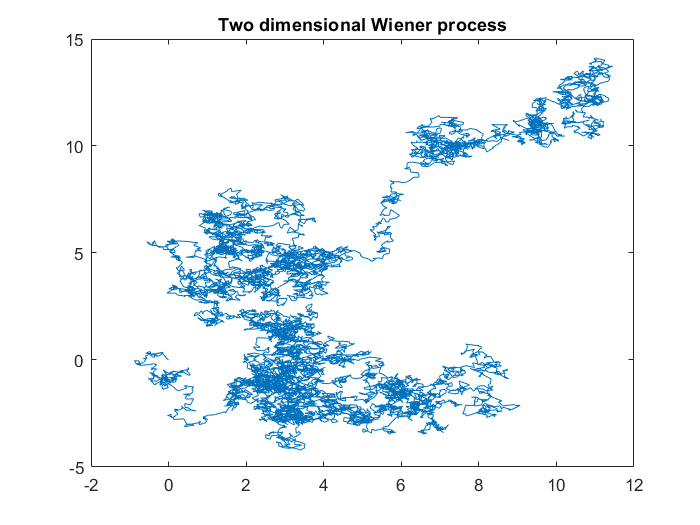

% Fill in your answer here:
seed61 = 123;
seed62 = 456;

[t6,x6,y6] = sim('m20p5',[0.01 1000]);
figure
plot(x6(:,1),x6(:,2))
title('Two dimensional Wiener process')

**Further Experiments with White Noise**

In this exercise the work started in Group Work Exercise 13 will be continued with the study of a second order low pass filter and the noise calculated using the Lyapunov equation. Consider a second order low pass filter ($\omega_0$=10 rad/s and $\zeta$=0.707)


$$\matrix{\dot{x}=v \cr \dot{v}=-\omega_0^2x-2\zeta\omega_0v+\omega^2_0u \cr y=x } \qquad (3)$$


driven by band-limited noise *u* with autocorrelation function


$$\textbf{R}(\tau)=\sigma^2_u\text{e}^{-\beta|\tau|}$$


 where $\sigma^2_u$=0.5 and $\beta$=10.

**Problem 6**

Using the Lyapunov equation find theoretical value of the covariance matrix **Q** as a function of the system parameters. Then solve numerically the Lyapunov equation using the Matlab command *lyap()*.

% Fill in your answer here:
format short

w = 10;
zeta = 0.707;
sigma_u = sqrt(0.5);
beta = 10;
V = 1;

A = [0 1;-w^2 -2*zeta*w];
B = [0 w^2]';
C = [1 0];
Aa = [-beta 0 0;0 0 1;w^2 -w^2 -2*zeta*w];
Ba = [sqrt(2*beta)*sigma_u 0 0]';

C = Ba*V*Ba';

Aaa = [0 1 0;-w^2 -2*zeta*w w^2; 0 0 -beta];
Bbb = [0;0;sqrt(2*beta)*sigma_u];
Cc = Bbb*V*Bbb';
% Solution of the Lyapunov equation for calculating the noise amplitudes
Q = lyap(Aa,C)

Q =     0.5000    0.1465    1.4646
    0.1465    0.2500    0.0000
    1.4646    0.0000   10.3576


Q2 = lyap(Aaa,Cc)

Q2 =     0.2500    0.0000    0.1465
    0.0000   10.3576    1.4646
    0.1465    1.4646    0.5000


**Problem 7**

Implement a Simulink model representing Equation 3 and simulate it for at least 1000 seconds. Export the input, the states and the output, and calculate the statistical properties of these signals. Compare the obtained results with those of Problem 1 and comment on them.

% Fill in your answer here:

